disp('cartesian manipulator')

cartesian manipulator


disp('Mendoza')

Mendoza


syms a1 a2 a3 a4 d1 d2 d3

%% Link lengths
a1 = 5;
a2 = 3;
a3 = 3;
a4 = 3;
%% Joint Variables
d1 = 5;
d2 = 5;
d3 = 5;

%% D-H Parameters [theta, d, r, alpha, offset]
% if prismatic joint: theta = theta, d = 0, offset = 1, after offset put the value of d

H0_1 = Link([0,0,0,pi/2,1,a1]);
H0_1.qlim = [0 0];

H1_2 = Link([pi/2,0,0,pi/2,1,a2]);
H1_2.qlim = [0 d1];

H2_3 = Link([pi/2,0,0,3*pi/2,1,a3]);
H2_3.qlim = [0 d2];

H3_4 = Link([0,0,0,0,1,a4]);
H3_4.qlim = [0 d3];

Cartesian = SerialLink([H0_1 H1_2 H2_3 H3_4], 'name', 'Cartesian')

 
Cartesian = 
 
Cartesian:: 4 axis, PPPP, stdDH, slowRNE                         
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|          0|         q1|          0|     1.5708|          5|
|  2|     1.5708|         q2|          0|     1.5708|          3|
|  3|     1.5708|         q3|          0|    4.71239|          3|
|  4|          0|         q4|          0|          0|          3|
+---+-----------+-----------+-----------+-----------+-----------+
 


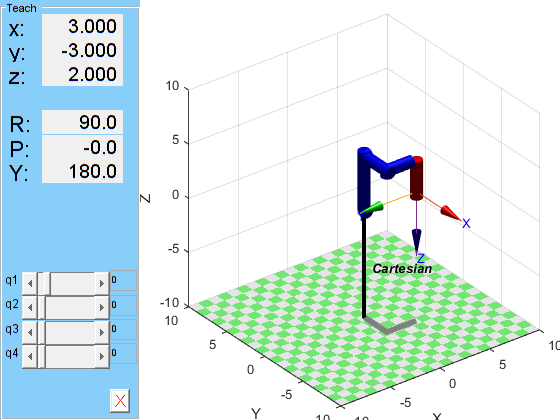

Cartesian.plot([0 0 0 0], 'workspace',[-10 10 -10 10 -10 10]) %plot at Origin position
Cartesian.teach